# Problem Set 3

## Problem 1

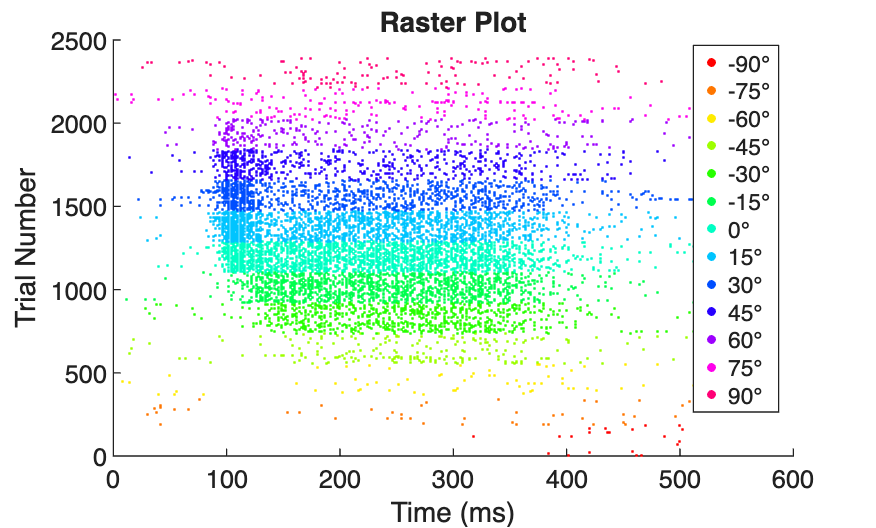

numTimes = size(mtNeuron.data, 1);
numDirections = size(mtNeuron.data, 2);
numTrials = size(mtNeuron.data, 3);

colors = hsv(numDirections);
directions = linspace(-90, 90, numDirections);

figure; hold on;
trial_offset = 0;
legend_handles = gobjects(numDirections,1);

for direction = 1:numDirections
    for trial = 1:numTrials
        % convert to ms
        spikes = find(mtNeuron.data(:, direction, trial)) * 2;
        y = (trial_offset + trial) * ones(size(spikes));

        plot(spikes, y, '.', 'Color', colors(direction, :), 'MarkerSize', 1);
    end
    
    legend_handles(direction) = plot(nan, nan, '.', ...
        'Color', colors(direction, :), 'MarkerSize', 10);
    
    trial_offset = trial_offset + numTrials;
end

xlabel('Time (ms)');
ylabel('Trial Number');
title('Raster Plot');
legend(legend_handles, string(directions) + "°", 'Location', 'best');

The neuron is directionally tuned and responds most strongly to -30, -45, 0, 15, 30, and 45 degrees. 

## Problem 2

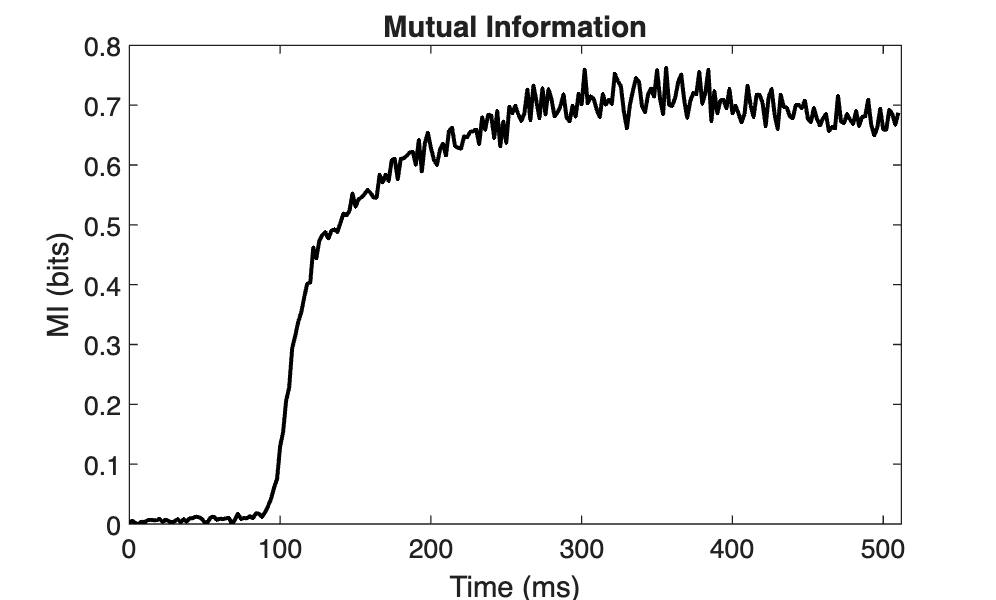

cumulative_spikes = cumsum(mtNeuron.data, 1);
num_directions = size(mtNeuron.data, 2);
num_trials = size(mtNeuron.data, 3);
num_time = size(mtNeuron.data, 1);
% I(T) = I(T_n, theta) = sum_n P_T(n)log_s(P_T(n|theta)/P_T(n))

fractions = [1/4, 1/3, 1/2, 2/3, 1]; % eq7
num_fracs = length(fractions);
MI_raw = zeros(num_time, num_fracs);

for fi = 1:num_fracs
    n_samp = floor(fractions(fi) * num_trials); 
    for t = 1:num_time

        counts = zeros(num_directions, n_samp);
        for d = 1:num_directions
            idx = randperm(num_trials, n_samp);
            counts(d, :) = cumulative_spikes(t, d, idx);
        end

        all_counts = counts(:);
        max_n = max(all_counts);
        count_vals = 0:max_n;
        num_vals = length(count_vals);

        % P(n|theta) based on histogram
        Pn_given_theta = zeros(num_directions, num_vals);
        for d = 1:num_directions
            for ni = 1:num_vals
                Pn_given_theta(d, ni) = mean(counts(d, :) == count_vals(ni));
            end
        end
        % P(n) = (1/num_directions) * sum_theta P(n|theta) eq2, avg
        Pn = mean(Pn_given_theta, 1);
        MI = 0;
        P_theta = 1 / num_directions; 

        for d = 1:num_directions
            % P(n | theta_d)
            Pn_d = Pn_given_theta(d, :);    
            mask = Pn_d > 0 & Pn > 0;
            MI = MI + P_theta * sum( Pn_d(mask) .* log2( Pn_d(mask) ./ Pn(mask)) );
        end

        MI_raw(t, fi) = MI;
    end
end
MI_corrected = zeros(num_time, 1);
inv_fracs    = 1 ./ fractions;

for t = 1:num_time
    p = polyfit(inv_fracs, MI_raw(t, :), 1);  
    MI_corrected(t) = p(2); % y-intercept = I_true
end

MI_corrected = max(MI_corrected, 0);
time_ms = (0:num_time-1) * 2;

figure;
plot(time_ms, MI_corrected, 'k-', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('MI (bits)');
title('Mutual Information');
xlim([0 512]);

Before the neuron responds, the cumulative spike count is very close to zero. We can see this in the time before 100ms on our plot where it looks mostly flat. This means that for every trial regardless of direction, the neuron hasn't fired so therefore mutual information will be 0. The rapid increase is when the neuron starts firing. Trials of the neuron's preferred direction cause a larger increase in cumulative spike count, while trials not of the neuron's preferred direction cause the cumulative spike count to stay around 0. This means that there is a greater difference between P(n) and P(n|theta), which causes the mutual information to increase as well. 

## Problem 3

n_boot = 1000;                        
MI_boot = zeros(num_time, n_boot);

for b = 1:n_boot
    boot_spikes = zeros(num_time, num_directions, num_trials);
    for d = 1:num_directions
        idx = randi(num_trials, 1, num_trials);
        boot_spikes(:, d, :) = cumulative_spikes(:, d, idx);
    end

    MI_raw_boot = zeros(num_time, num_fracs);

    for fi = 1:num_fracs
        n_samp = floor(fractions(fi) * num_trials);

        for t = 1:num_time
            counts = zeros(num_directions, n_samp);
            for d = 1:num_directions
                idx = randperm(num_trials, n_samp);
                counts(d, :) = boot_spikes(t, d, idx);
            end

            all_counts = counts(:);
            max_n = max(all_counts);
            count_vals = 0:max_n;
            num_vals = length(count_vals);

            Pn_given_theta = zeros(num_directions, num_vals);
            for d = 1:num_directions
                for ni = 1:num_vals
                    Pn_given_theta(d, ni) = mean(counts(d, :) == count_vals(ni));
                end
            end

            Pn = mean(Pn_given_theta, 1);
            MI = 0;
            P_theta = 1 / num_directions;
            for d = 1:num_directions
                Pn_d = Pn_given_theta(d, :);
                mask = Pn_d > 0 & Pn > 0;
                MI = MI + P_theta * sum(Pn_d(mask) .* log2(Pn_d(mask) ./ Pn(mask)));
            end
            MI_raw_boot(t, fi) = MI;
        end
    end

    for t = 1:num_time
        p = polyfit(inv_fracs, MI_raw_boot(t, :), 1);
        MI_boot(t, b) = p(2);
    end
    MI_boot(:, b) = max(MI_boot(:, b), 0);
end

MI_low  = prctile(MI_boot, 2.5,  2); 
MI_high = prctile(MI_boot, 97.5, 2); 

We need to resample within each direction condition and not pool all the trials together before bootstrapping. This is to preserve the P(n|theta) conditional probability. We also need to make sure we do the entire bias-error correction process for each resampling. If we do not, we will have the same upward bias that we would've had if we calculated mutual information based only on the entire sample size (N).

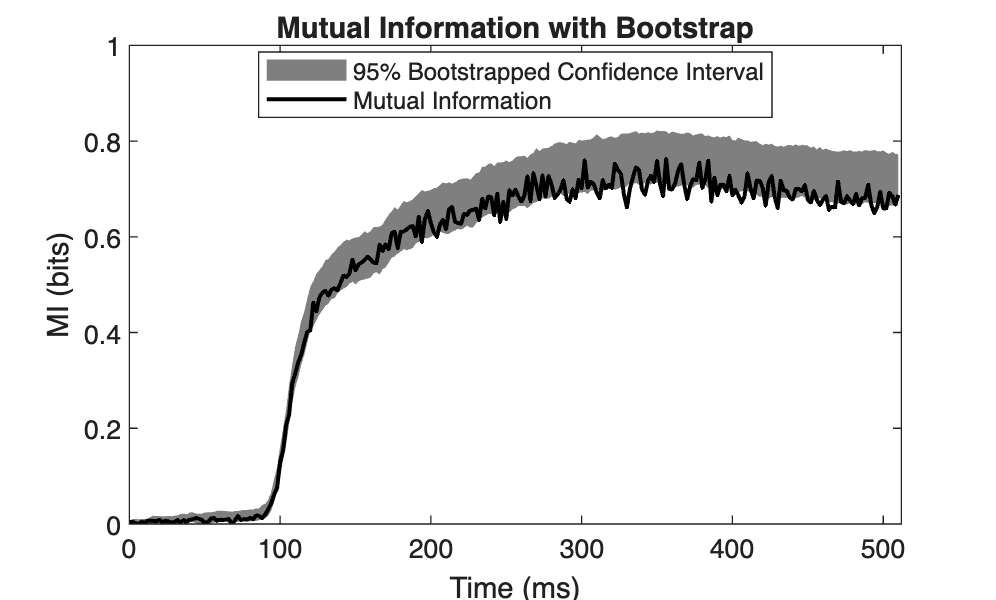

figure;
fill([time_ms, fliplr(time_ms)], ...
     [MI_low', fliplr(MI_high')], ...
     [0 0 0], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
hold on;
plot(time_ms, MI_corrected, 'k-', 'LineWidth', 1.5);
xlabel('Time (ms)');
ylabel('MI (bits)');
title('Mutual Information with Bootstrap');
xlim([0 512]);
legend('95% Bootstrapped Confidence Interval', 'Mutual Information', 'Location', 'best');